close all
clear
clc

定义仿真时刻n、激励序列x和响应序列y

n = [0:20]';
x = [1;0.5];
y = 0.5.^n;

解卷积计算单位样值响应真值

[h,r] = deconv(y,x);

定义理论解得的单位样值响应

h0 = 0.5.^n.*(mod(n,2)==0);

绘图，上图是计算值，下图是真值，对比两个完全相同

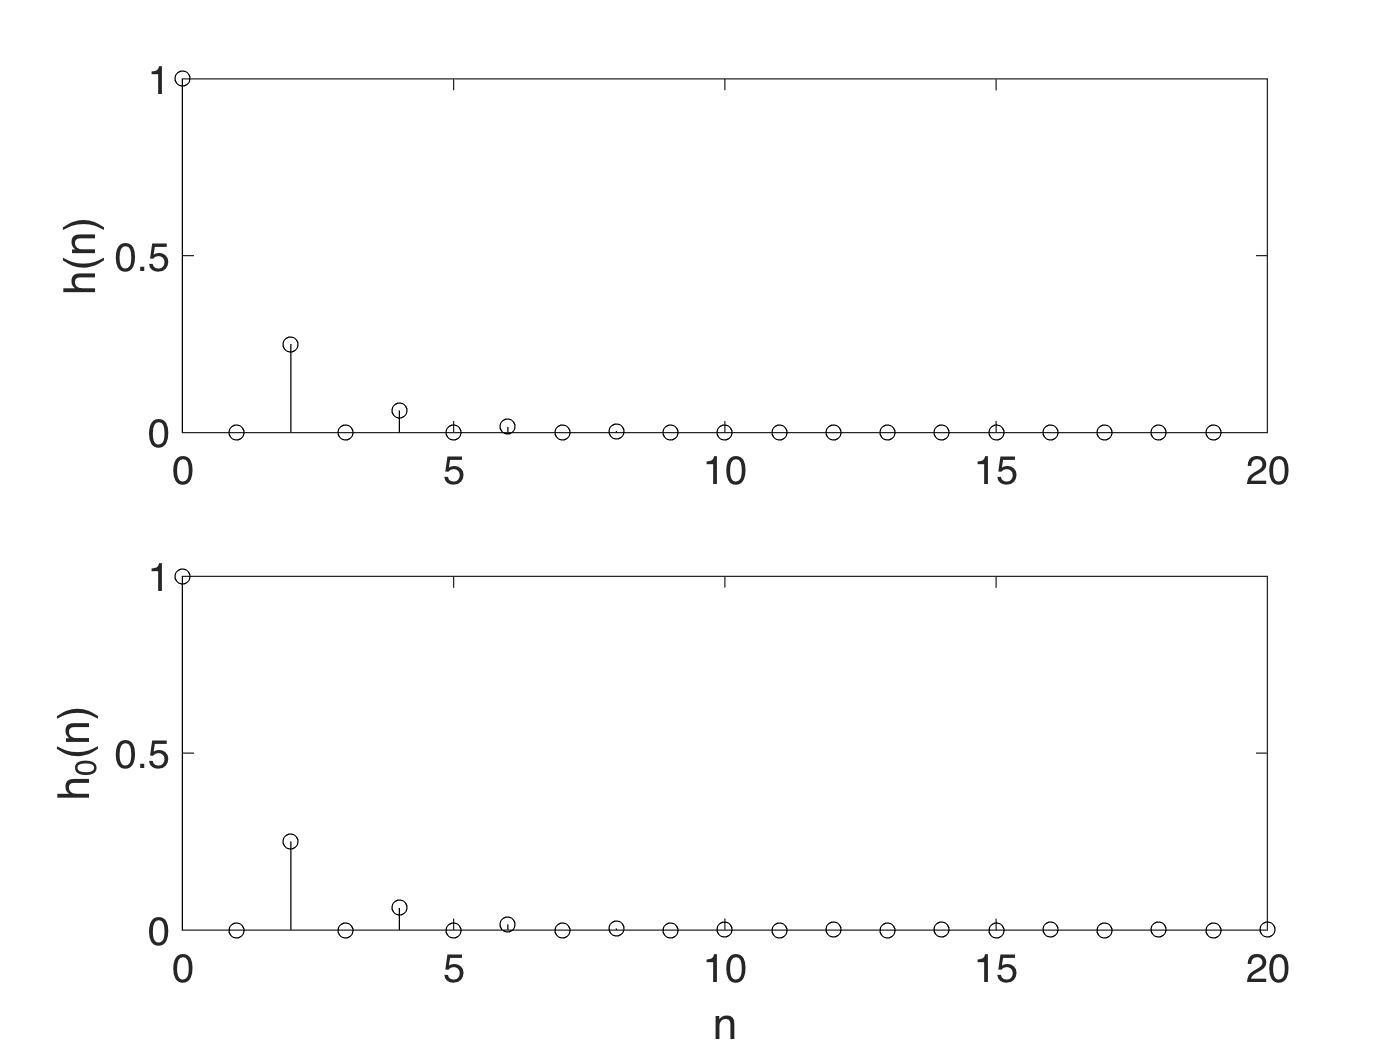

figure;
box on, hold on;
subplot(2,1,1), hold on, box on;
set(gca,'FontSize',16);
stem([0:length(h)-1]',h,'k');
ylabel('h(n)');
subplot(2,1,2), hold on, box on;
stem([0:length(h0)-1]',h0,'k');
set(gca,'FontSize',16);
xlabel('n');
ylabel('h_{0}(n)');